# Getting Started with EnergyPlus Co-simulation Toolbox

This script demonstrates the functionality of the toolbox in a small office building simulation scenario.

## Create a co-simulation object

The main component of the toolbox is the 'mlep' class containing all the necessary tools to configure and run EnergyPlus co-simulation within the Matlab environment. 

% Instantiate the co-simulation tool
ep = mlep;

## Prepare simulation

Specify building simulation configuration file (.IDF). We will use a modified example file from EnergyPlus installation (*EnergyPlusVx-x-x\ExampleFile\SmOffPSZ.idf*). It is a 2 story small office building with a Packaged Single Zone (PSZ) air conditioning system. Each floor divided into a north & a south zone. Each of the 4 occupied zones is served by a PSZ system. 

Make sure that the IDF file is on the MATLAB  search path or specify an absolute path to the file. We will use an example IDF file from the toolbox examples folder (*<toolbox-path>\examples\legacy_example\*), where the input / output specification is already prepared.

% Building simulation file
ep.idfFile = 'SmOffPSZ';

Specify weather file - an EnergyPlus Weather data file (.EPW). You can obtain weather files at [https://energyplus.net/weather.](https://energyplus.net/weather.) We will use a weather file that comes also comes with the EnergyPlus installation (*EnergyPlusVx-x-x\WeatherFiles\USA_IL_Chicago-OHare.Intl.AP.725300_TMY3.epw*). Make sure that the weather file is on the MATLAB search path or specify a full path.

% Weather file
ep.epwFile = 'USA_IL_Chicago-OHare.Intl.AP.725300_TMY3';

Note: The start of the simulation period as well as the timestep and necessary inputs and available outputs are defined by the the EnergyPlus simulation file (.IDF). 

## Input / output configuration

Load the IDF by calling the *initialize* method. If you don't need to check the configuration, you can skip this step as the initialization is called by the *start *method used later. 

% Initialize
ep.initialize; 

See all the inputs specified in the IDF file (the EnergyPlus inputs are specified in the *ExternalInterface* environment).

inputs = ep.inputTable

inputs = 2×2 table
       Name                   Type            
    __________    ____________________________

    "schedule"    "HeatingSetpointTemperature"
    "schedule"    "CoolingSetpointTemperature"


The results should be a *HeatingSetpointTemperature* and a *CoolingSetpointTemperature,* which are the thermostat setpoints for all the zones. 

See all the outputs the co-simulation will return (in the IDF file look for *Output:Variable*)

outputs = ep.outputTable

outputs = 5×3 table
        Name                          Type                       Period  
    _____________    ______________________________________    __________

    "ENVIRONMENT"    "Site Outdoor Air Drybulb Temperature"    "timestep"
    "ZSF1"           "Zone Mean Air Temperature"               "timestep"
    "ZNF1"           "Zone Mean Air Temperature"               "timestep"
    "ZSF1"           "Zone Operative Temperature"              "timestep"
    "ZNF1"           "Zone Operative Temperature"              "timestep"


The timestep is also specified in the IDF file (in a number-of-steps-per-hour format, look for *Timestep* in the IDF file). The initialization routine has loaded the IDF file and calculated the timestep in seconds. The EnergyPlus simulation start day is defined under the *RunPeriod *environment of the IDF file.

Note: Make sure that the EnergyPlus simulation timestep adheres to your simulation scenario, i.e. that you expect the EnergyPlus dynamics to step by the specified timestep. 

timestep = ep.timestep %[s]

timestep = 600

## Simulation

Specify simulation length.

% Simulation length
endTime = 4*24*60*60; %[s]

Prepare logging variables.

% Logging
logTable = table('Size',[0, 1 + ep.nOut],...
    'VariableTypes',repmat({'double'},1,1 + ep.nOut),...
    'VariableNames',[{'Time'}; ep.outputSigName]);

Start the EnergyPlus process and initialize communication. 

% Start co-simulation
ep.start;

Run simulation.

t = 0;
iLog = 1;
while t < endTime
    
    % Specify inputs
    u = [20 25]; % [heating setpoint, cooling setpoint]
    
    % Send inputs & get outputs from EnergyPlus
    y = ep.step(u); 
    
    % Obtain elapsed simulation time 
    t = ep.time; %[s]
    
    % Or alternatively by using 'read' and 'write' methods. Please note that the 'read'
    % method must preceed the 'write' method.
    %{
    % Get outputs from EnergyPlus
    [y, t] = ep.read;
    
    % Send inputs to EnergyPlus
    ep.write(u,t); 
    %}
    
    % Log data
    logTable(iLog, :) = num2cell([t y']);
    iLog = iLog + 1;    
end

Stop the EnergyPlus process and communication

% Stop co-simulation
ep.stop;

## Plot results

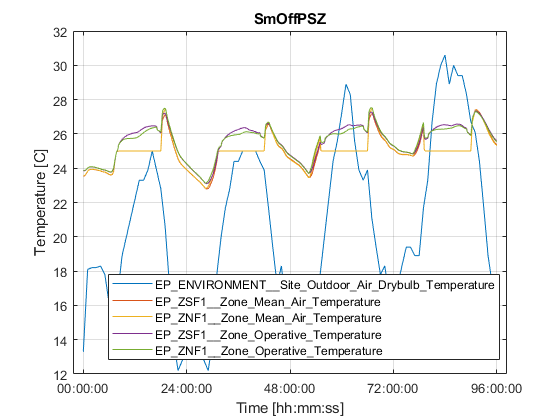

plot(seconds(table2array(logTable(:,1))),...
    table2array(logTable(:,2:end)));
xtickformat('hh:mm:ss');
title(ep.idfFile);
xlabel('Time [hh:mm:ss]');
ylabel('Temperature [C]');
grid on
legend(logTable.Properties.VariableNames(2:end),'Interpreter','none','Location','best');

clear ep endTime inputs outputs logTable iLog t timestep u y